img = imread("Puzzle_06.jpg");

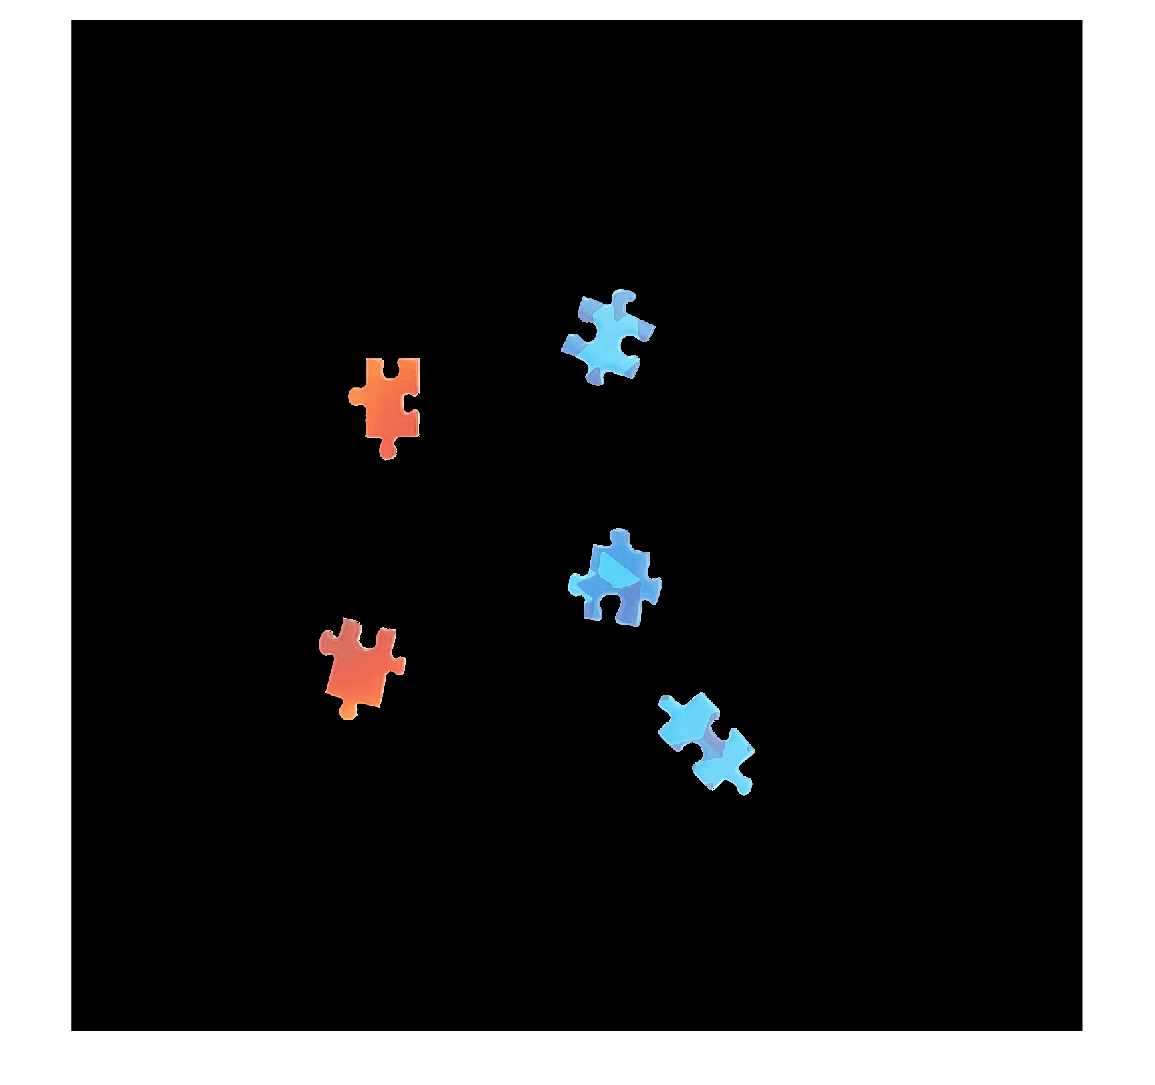

I = rgb2hsv(img);

channel1Min = 0.885;
channel1Max = 0.140;
channel2Min = 0.119;
channel2Max = 1.000;
channel3Min = 0.689;
channel3Max = 1.000;

redMask = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
I = rgb2hsv(img);
channel1Min = 0.484;
channel1Max = 0.739;
channel2Min = 0.119;
channel2Max = 1.000;
channel3Min = 0.689;
channel3Max = 1.000;
blueMask = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);

BW = redMask | blueMask;
maskedRGBImage = img;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
G = im2gray(maskedRGBImage);

BW = imbinarize(G, 'adaptive', 'Sensitivity', 0.420000, 'ForegroundPolarity', 'bright');
BW = imfill(BW, 'holes');
BW = imcomplement(BW);
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);
BW = ~(BW);
maskedRGBImage = img;
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
hsv = rgb2hsv(maskedRGBImage);
K = 3;
sing = im2single(hsv);
labels = imsegkmeans(sing, K);

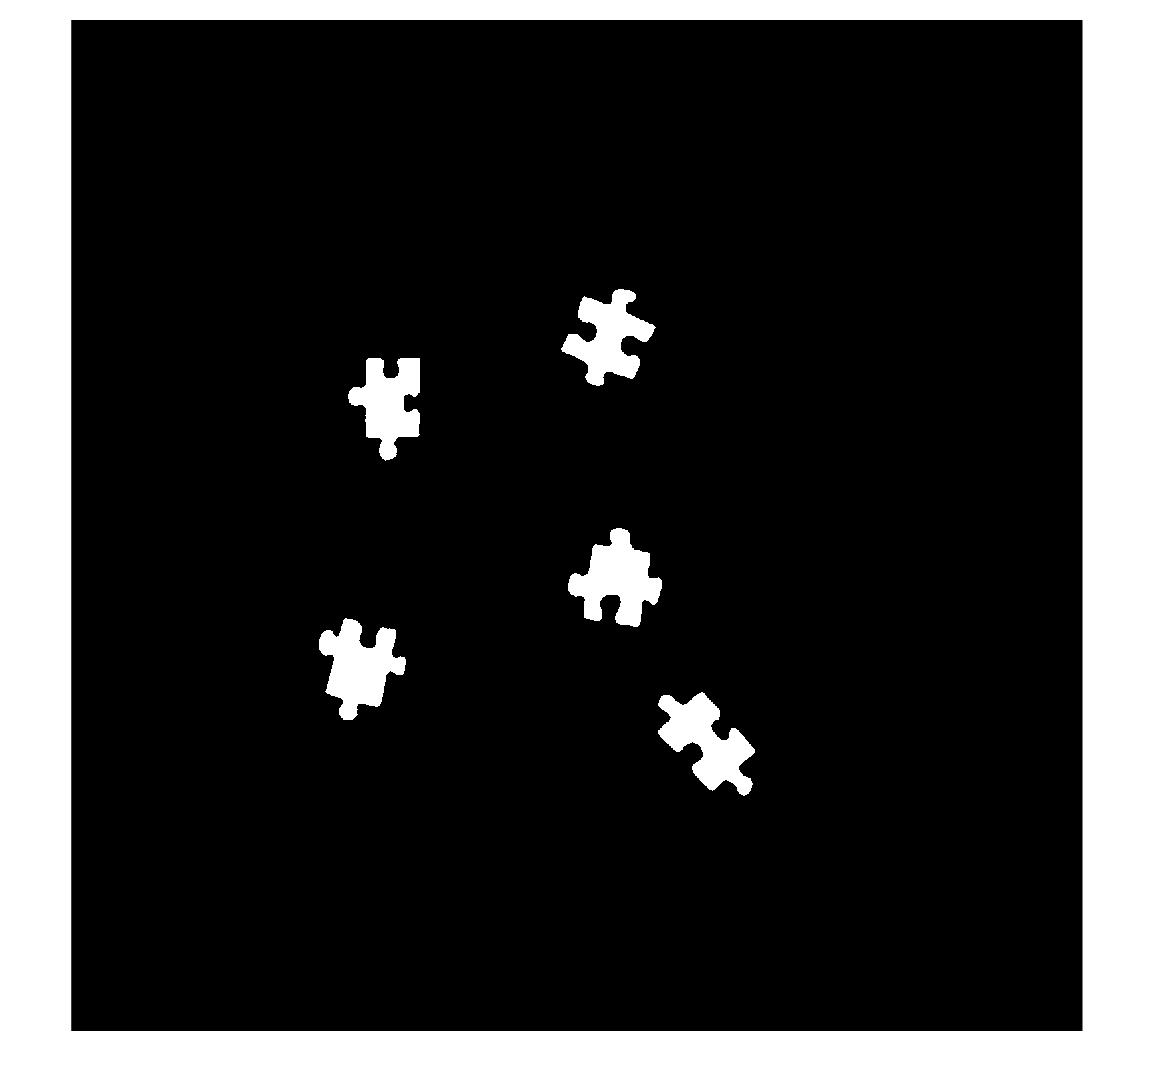

imshow(BW)

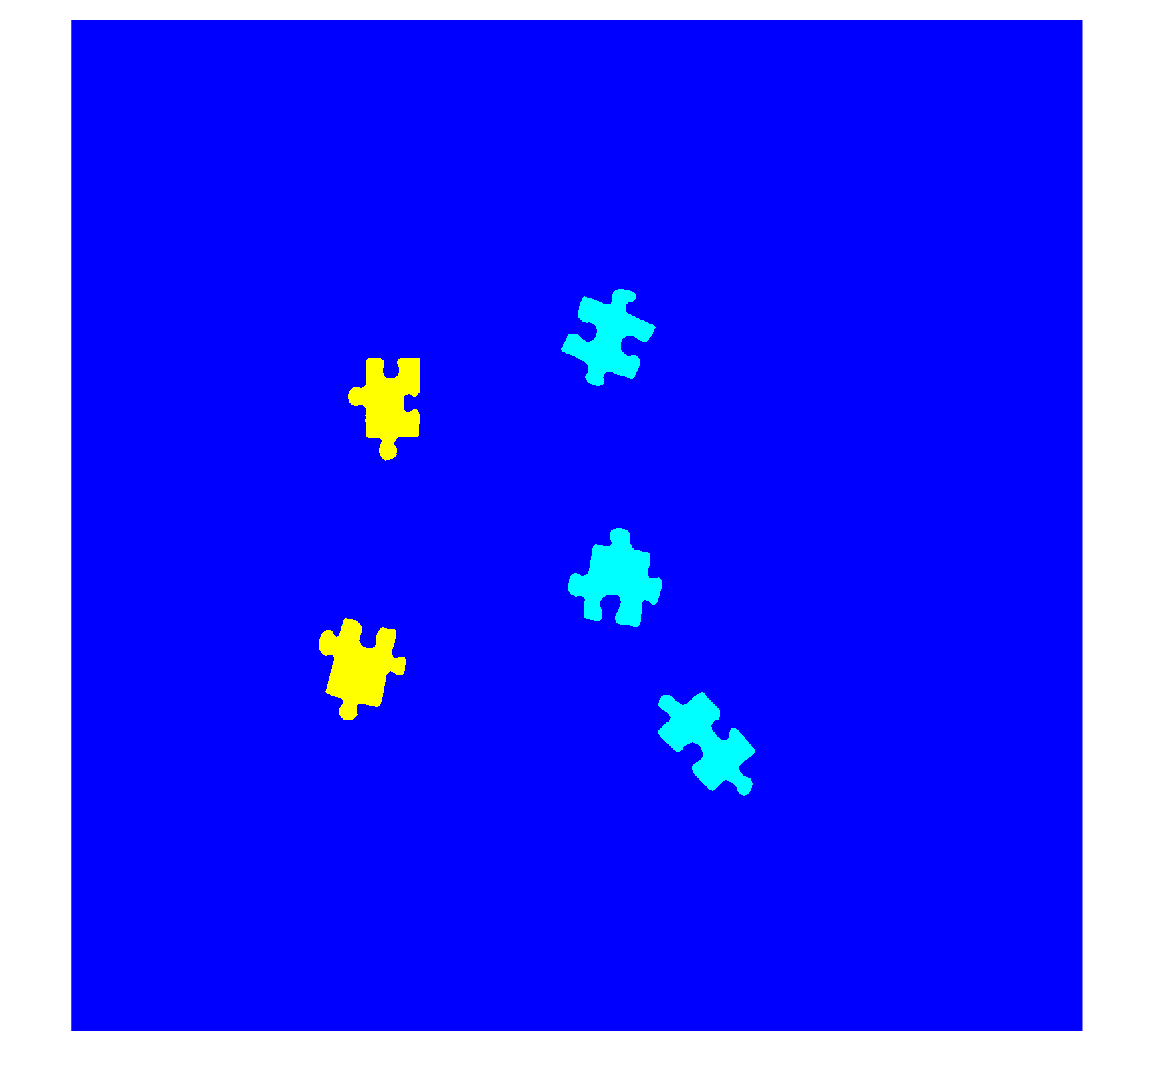

imshow(label2rgb(labels))

regionprops("table", BW)

ans = 5×3 table
    Area         Centroid                    BoundingBox            
    _____    ________________    ___________________________________

    11081    431.38       967    370.5     894.5       130       153
     9809    475.64    573.78    414.5     505.5       108       154
    10199    803.68    475.18    733.5     402.5       141       145
    11321    816.71    838.05    742.5     760.5       141       147
    11072     950.9    1080.1    877.5    1005.5       146       155
